T1 = readtable("eps_k.csv");
T2 = readtable("k_eps.csv");
T3 = readtable("hord_eps_k.csv");
T4 = readtable("hord_k_eps.csv");

f = @(x) x.^4 - 4*x.^3 + 4*x.^2 - 4;
fd = @(x) 4*x.^3 + 12*x.^2 + 8*x;
fdd = @(x) 12*x.^2 + 24*x + 8;

f_x4 = @(x) 1 - 4*x + 4*x.^2 - 4*x.^4;

format long

Получим "точные" значения наших корней:

cres1 = fzero(f, 2)

cres1 =    2.732050807568877


cres2 = fzero(f, -1)

cres2 =   -0.732050807568877


Оценить получиться только верхнюю и нижнюю границу положительных корней, у отрицательных при подстановке a0 < 0:

x_ubound = 1 + nthroot(4/1, 2)

x_ubound =      3


figure
hold on
grid on
title("Производные f(x)", Interpreter="tex");
ylabel("y");
xlabel("x");
legend("$\psi'(x)$", "$\psi''(x)$", Interpreter="latex")

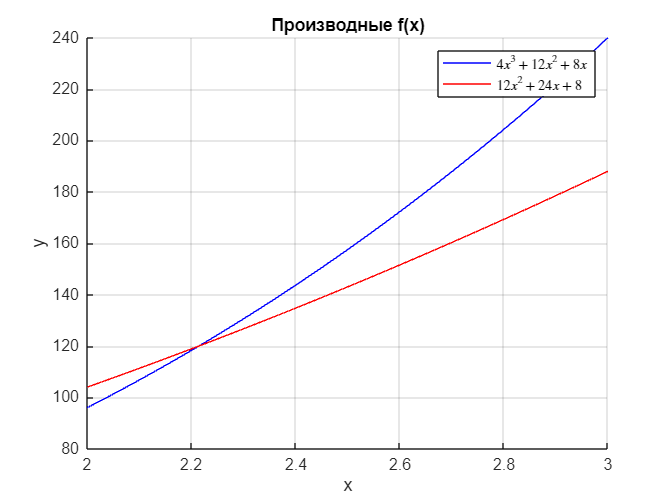

fplot(fd, [2, 3], "b-")
fplot(fdd, [2, 3], "r-")

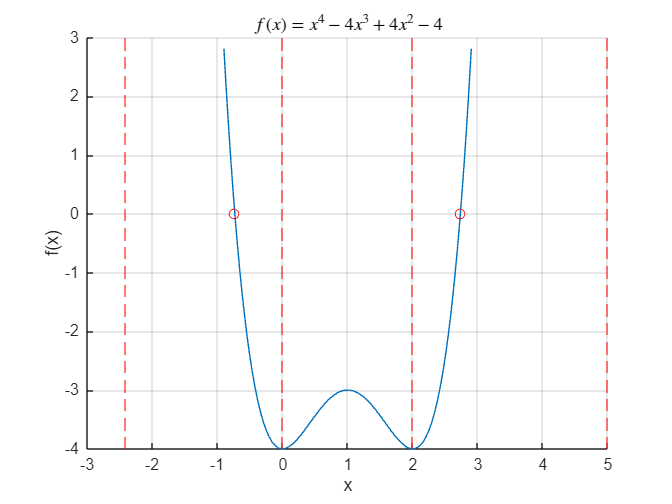


%x_lbound = -(1 + nthroot(4/1, 1))
figure
hold on
grid on
fplot(f, [-0.9, 2.9]);
plot(cres1, f(cres1), "or")
plot(cres2, f(cres2), "or")
xline([5], 'r--');
xline([2], 'r--');
xline([-2.4142], 'r--');
xline([0], 'r--');
title("$$f(x) = x^4 - 4x^3 + 4x^2 - 4$$", 'Interpreter','latex')
xlabel("x")
ylabel("f(x)")

fd(2)

ans =     96


fd(3)

ans =    240


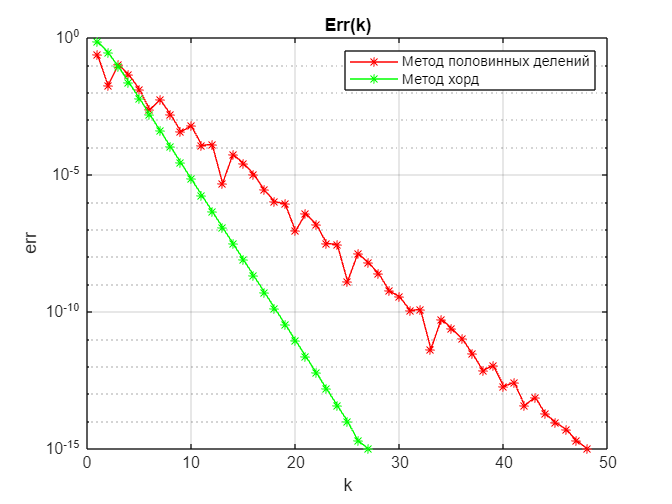

figure
semilogy(T1.k, T1.eps, "r*-", T3.k, T3.eps, "g*-");
grid on
legend('Метод половинных делений','Метод хорд');
title("Err(k)")
xlabel("k")
ylabel("err")

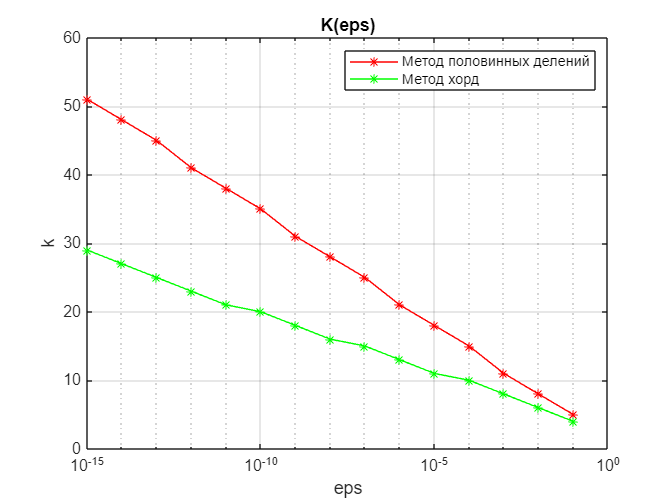

figure
semilogx(T2.eps, T2.k, "r*-", T4.eps, T4.k, "g*-");
legend('Метод половинных делений','Метод хорд');
title("K(eps)")
xlabel("eps")
ylabel("k")
grid on

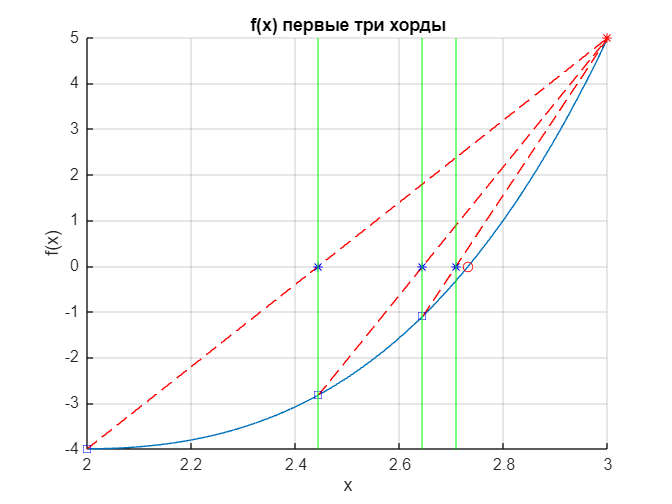

figure
hold on
grid on
fplot(f, [2, 3]);
plot(cres1, f(cres1), "or")
plot(3, f(3), "r*")
title("f(x) первые три хорды")
xlabel("x")
ylabel("f(x)")

for i = 1:3
    cf = @(x) ((f(3) - f(T3.x(i))) / (3 - T3.x(i))) * (x - T3.x(i)) + f(T3.x(i));
    fplot(cf, [T3.x(i), 3], 'r--');
    plot(T3.x(i), f(T3.x(i)), "bs");
    plot(T3.x(i + 1), 0, "b*");
    xline(T3.x(i + 1), "g*")
end

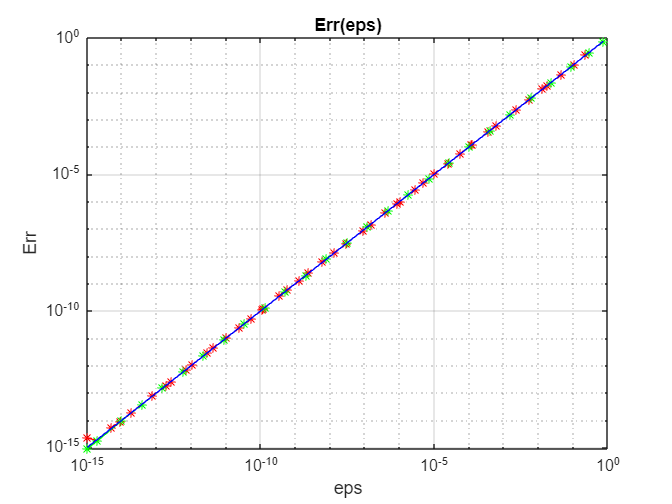

figure
Err1 = abs(T1.x - cres1);
Err3 = abs(T3.x - cres1);
loglog(T1.eps, Err1, 'r*-');
hold on;
grid on;
loglog(T3.eps, Err3, 'g*-');
loglog(T3.eps, T3.eps, 'b-');
title("Err(eps)")
xlabel("eps")
ylabel("Err")

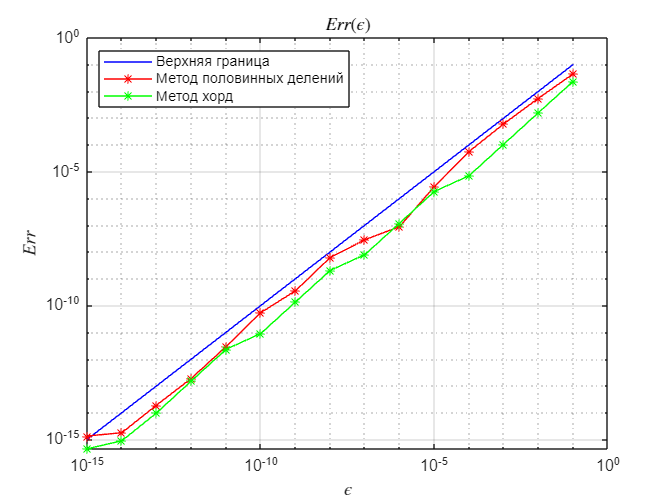

figure
res1 = abs(T2.x - cres1);
res2 = abs(T4.x - cres1);
loglog(T2.eps, T2.eps, 'b-')
hold on;
grid on;
loglog(T2.eps, res1, 'r*-')
loglog(T4.eps, res2, 'g*-')
title("$Err(\epsilon)$", 'Interpreter', 'latex')
xlabel("$\epsilon$", Interpreter="latex")
ylabel("$Err$", Interpreter="latex")
legend('Верхняя граница', 'Метод половинных делений','Метод хорд', Location='northwest');

slope_half = -1.44248;
slope_err_half = 0.00745;


slope_hord = -0.75226;
slope_err_hord = 0.00885;

t_slope_hord = -0.48858;
t_slope_err_hord = 0.00797;

display((slope_hord + t_slope_hord)/2)

  -0.620420000000000



display((slope_err_hord + t_slope_err_hord)/2)

   0.008410000000000

